# UVP6-LP sensibility / temperature

Picheral 2020/07/24

clear all
close all
clc
scrsz = get(0,'ScreenSize');
warning('OFF');


## Select Projet

selectprojet = 0;
while (selectprojet == 0)
    folder = uigetdir('',['Select UVP6 project directory']);
    if strcmp(folder(4:6),'uvp')
        selectprojet = 1;
    else
        disp(['The selected project ' folder ' is not correct. ']);
    end
end
raw_folder = [folder,'\raw\'];
results_folder = [folder,'\results\'];
if exist(results_folder) ~= 7
    mkdir(folder,'\results\');
end
disp(['Project :',folder])

Project :Z:\uvp6_sn000008lp_20200727_test_temperature



% ------ Liste des répertoires séquence --------
seq = dir([raw_folder '\2*']);
N_seq = size(seq,1);

## Settings

segmentation = 50;
angle_limit = 2;
pixel = 0.073;
area = .151 * .1805;
disp(['Threshold                  : ',num2str(segmentation)])

Threshold                  : 50


disp(['UVP6 pixel [mm]            : ',num2str(pixel)])

UVP6 pixel [mm]            : 0.073


## Loop on experiments


% Boucle sur les séquences
for j =1 : N_seq
    
    disp([seq(j).folder,'\',seq(j).name])
    %     cd(raw_folder);
    data_seq = [];
    
    % open data.txt file. path is the path for the text file stored in each sequence folder
    path = [seq(j).folder,'\',seq(j).name,'\',seq(j).name,'_data.txt'];
    
    % lecture metadata
    [sn,day,cruise,base_name,pvmtype,soft,light,shutter,threshold,volume,gain,pixel,Aa,Exp] = uvp6_read_metadata_from_datafile(folder,path);
    
    % Boucle sur les images
    
    % read data of the sequence
    % T is the table with all the lines of the text file, seperated in two tables : first part is the begnning with the date and time, pressure and black image flag
    %20190724-123151,22.31,34.50,1:  1,1048,41.7,14.5; 2,26,38.2,5.6;    3,1,66.0,28.5;
    [data, meta] = Uvp6DatafileToArray(path);
    
    %Initialisation of the variables updated for each line of the text
    %file / each image
    [n,m]=size(data);
    
    index = 1;
    for h=1:n
        % Avancement
        if h/100==floor(h/100);            disp(num2str(h));         end
        
        % -------- VECTEURS METADATA -------
        C = strsplit(meta{h},{','});
        try
            time_data =     datenum(datetime(char(C(1)),'InputFormat','yyyyMMdd-HHmmss-SSS'));
        catch
            time_data =     datenum(datetime(char(C(1)),'InputFormat','yyyyMMdd-HHmmss'));
        end
        prof_data =     str2double(C{2});
        temp_data =     str2double(C{3});
        Flag = str2double(C{4});
        
        if isempty(strfind(data{h},'OVER')) && isempty(strfind(data{h},'EMPTY')) && exist([seq(j).folder,'\',seq(j).name,'\',char(C(1)),'.png']) ==2
            % ouverture image et analyse
            img = imread([seq(j).folder,'\',seq(j).name,'\',char(C(1)),'.png']);
            
            % Figure de la première image
            if h == 1
                fig1 = figure('name','Raw image','Position',[50 50 600 600]);
            end
            
            % Measure intensity profiles and limits to adjust angle
            limits = [];
            Intensity = [];
            img_crop_mean_norm = [];
            for i = 1 : 18
                % i=1 and i=2 for extrem part of the light beam
                % NEW : i=3:18 for completing the intensity measurement
                if i == 1
                    img_crop = img(100:200,700:end-700);
                elseif i ==2
                    img_crop = img(end-200:end-100,700:end-700);
                else
                    img_crop = img(200+100*(i-3):200+100*(i-3)+100,700:end-700);
                end
                img_crop_mean = mean(img_crop);
                % Intensity normalization
                min_plot = min(img_crop_mean);
                max_plot = max(img_crop_mean);
                ratio = (img_crop_mean - min_plot) *(255/max_plot);
                img_crop_mean_norm(i,:) = ratio;
                aa = find(ratio > segmentation);
                limits(i,1) = aa(1);
                limits(i,2) = aa(end);
                Intensity(i,1) = mean(img_crop_mean(aa));
            end
            
            % Process angle
            shift = (limits(1,2) + limits(1,1))/2 - (limits(2,2) + limits(2,1))/2 ;
            dist = (size(img,2)-300);
            angle_deg = asind(abs(shift)/dist);
            
            % Angle warning
            if abs(angle_deg) > angle_limit
                disp('ANGLE of light beam > 2°, results may be biased')
            end
            
            % Correct image for rotation
            if shift < 0 ; angle_deg = -1 * angle_deg; end
            img_crop = img(:,round(mean(mean(limits,2))) - 500 +700:round(mean(mean(limits,2)))+500 +700);
            img_rot = imrotate(img_crop,angle_deg + 90,'loose');
            
            thick_left = pixel * (limits(1,2) - limits(1,1));
            thick_right = pixel * (limits(2,2) - limits(2,1));
            
            % Intensity measurements
            mean_left = Intensity(1);
            mean_right = Intensity(2);
            
            if h == 1
                imshow(img_rot);
            end
            data_seq(index,:) = [time_data prof_data temp_data mean([thick_left,thick_right]) mean(Intensity)];
            index = index +1;
  
            end
    end
    

### Display experimetal data

    fig2 = figure('name','Raw image','Position',[50 50 900 900]);
    
    % temperature en fonction du temps
    subplot(2,2,1)
    plot(datetime(datestr(data_seq(:,1))),data_seq(:,3))
    xlabel('Time');
    ylabel('Temperature [°C]');
    ylim([5 40]);
    
    title([sn,'  ',light,' : ',day]);
    
    % profondeur en fonction de la température
    subplot(2,2,2)
    plot(data_seq(:,3),data_seq(:,2))
    xlabel('Temperature [°C]') ;
    xlim([5 40]);
    ylabel('Z [dbars]');
    ylim([-2 2]);    
    
    % epaisseur moyenne en fonction de la température
    subplot(2,2,3)
    plot(data_seq(:,3),data_seq(:,4))
    xlabel('Temperature [°C]') ;
    xlim([5 40]);
    ylabel('Thickness [mm]');
    ylim([21 25]);    
    
    % intensité moyenne en fonction de la température
    subplot(2,2,4)
    plot(data_seq(:,3),data_seq(:,5))
    xlabel('Temperature [°C]') ;
    xlim([5 40]);
    ylabel('Intensity');
    ymin = 10*floor((min(data_seq(:,5)))/10);
    ylim([ymin ymin+20]);   
    
    
    % sauvegarde de la figure
    
    
    

### Save sequence data

Z:\uvp6_sn000008lp_20200727_test_temperature\raw\20200730-122046


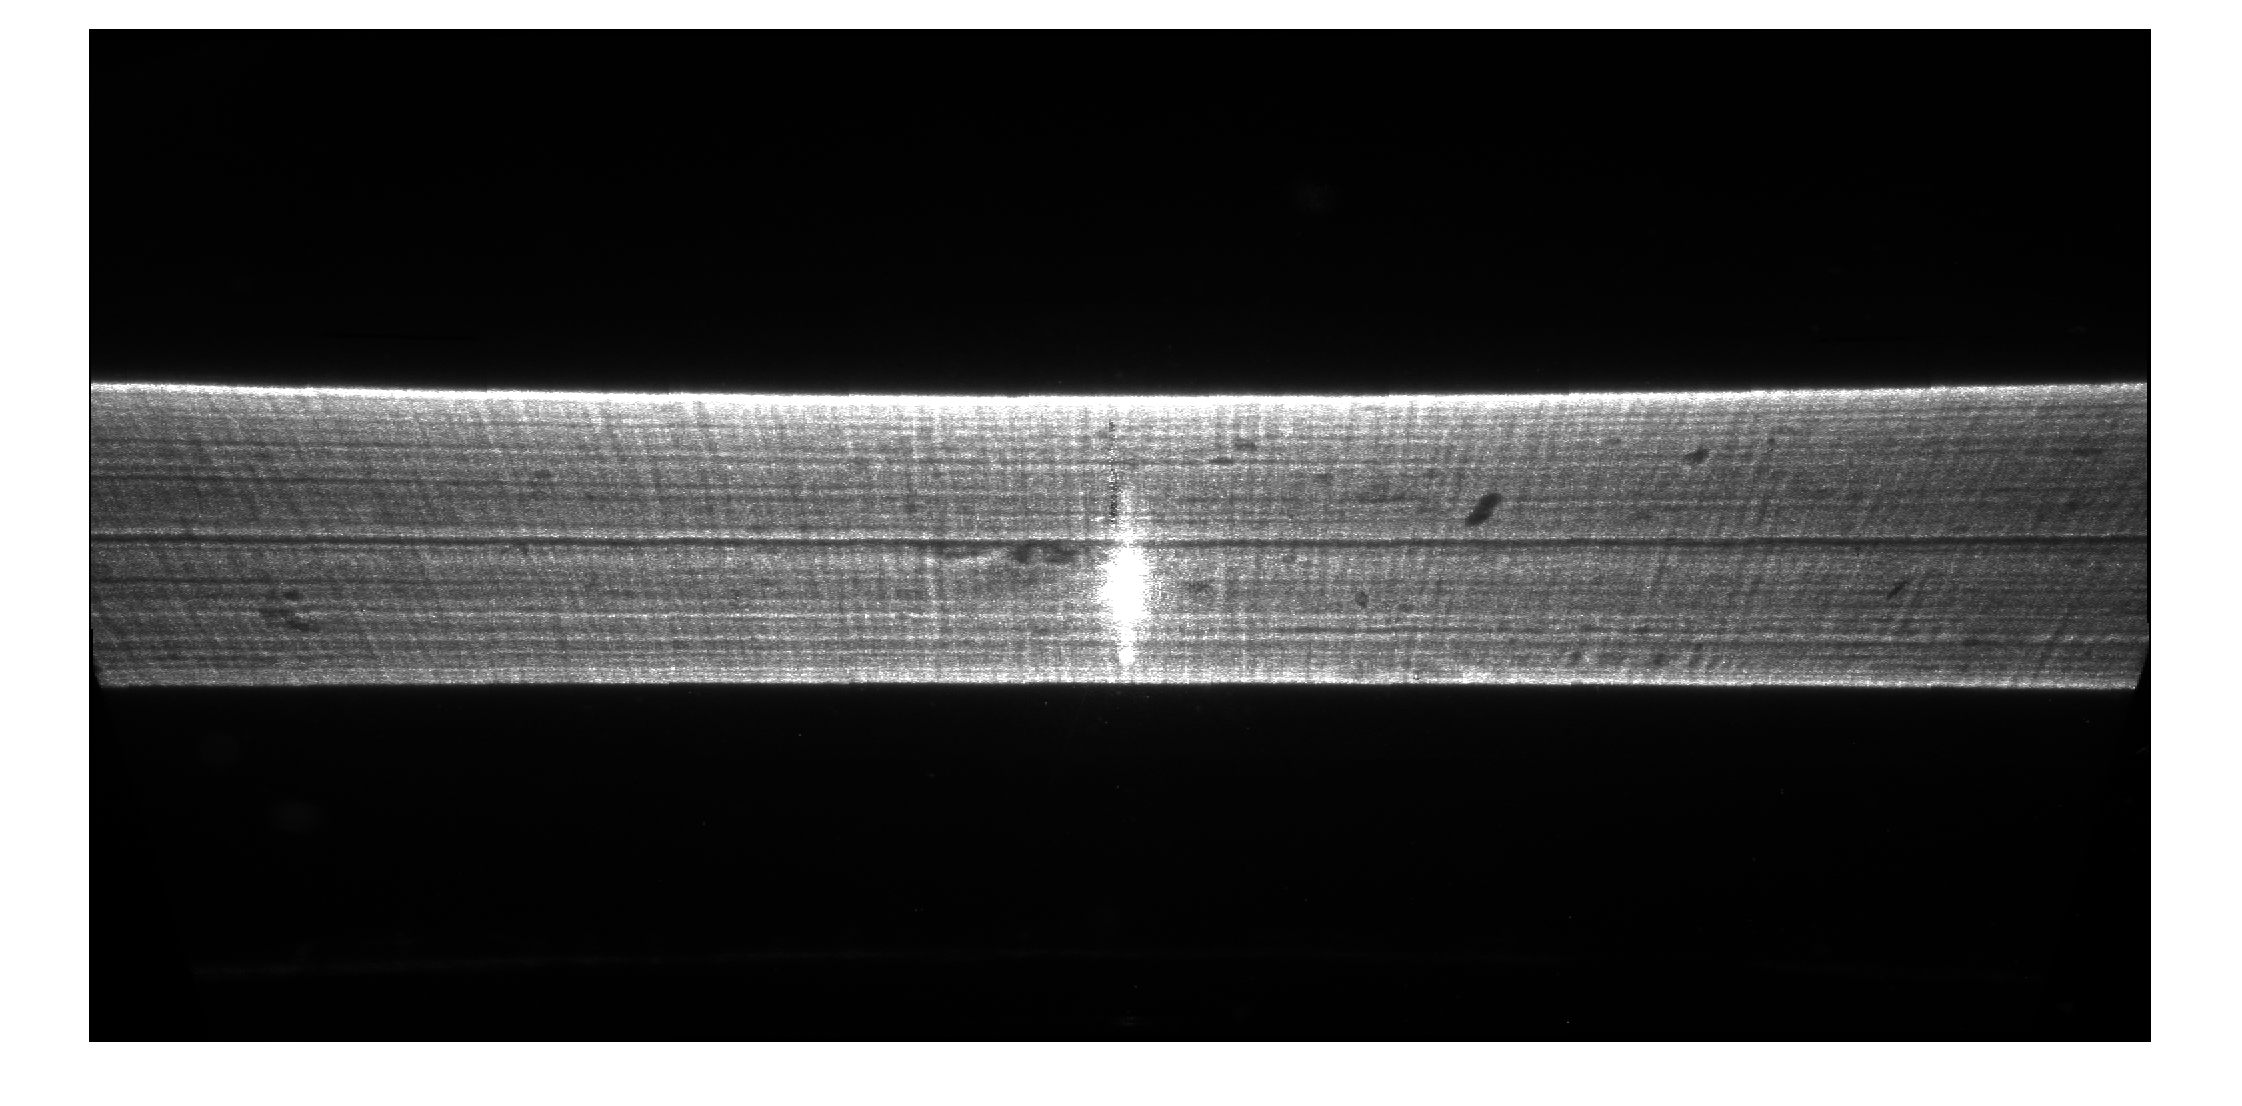

100
200
300
400
500
600
700
800
900
1000


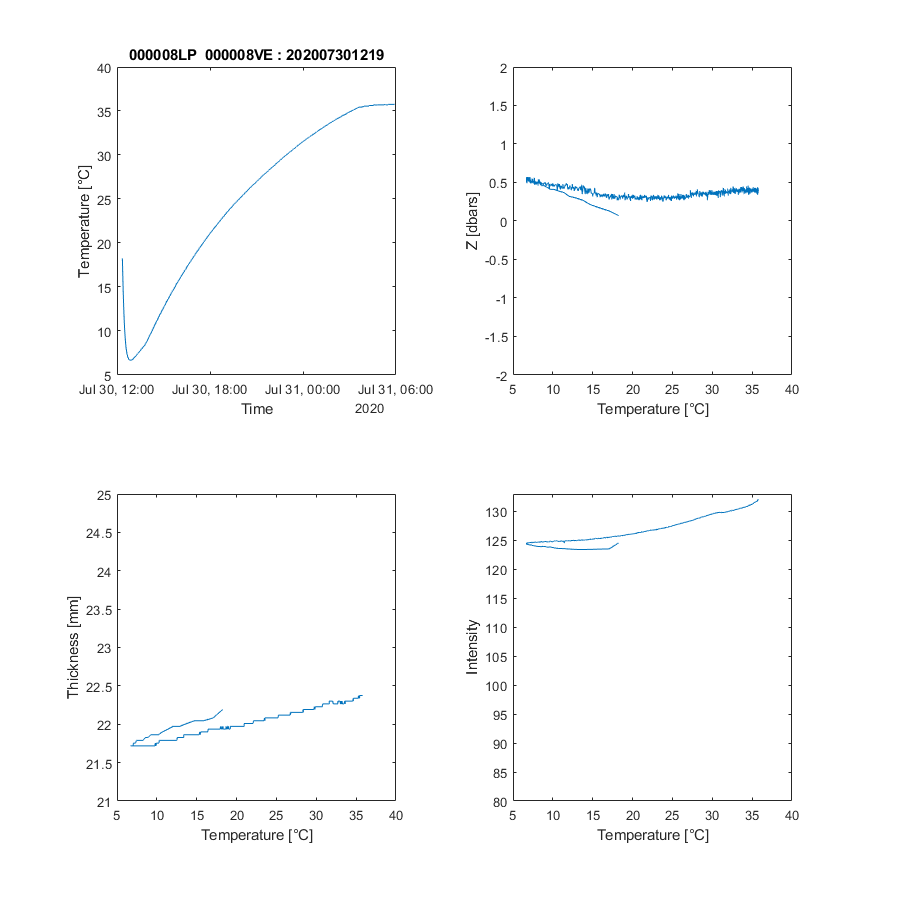

    cd(results_folder)
    eval( ['save uvp6_intensity_temperature_',seq(j).name,'.mat data_seq'])
end